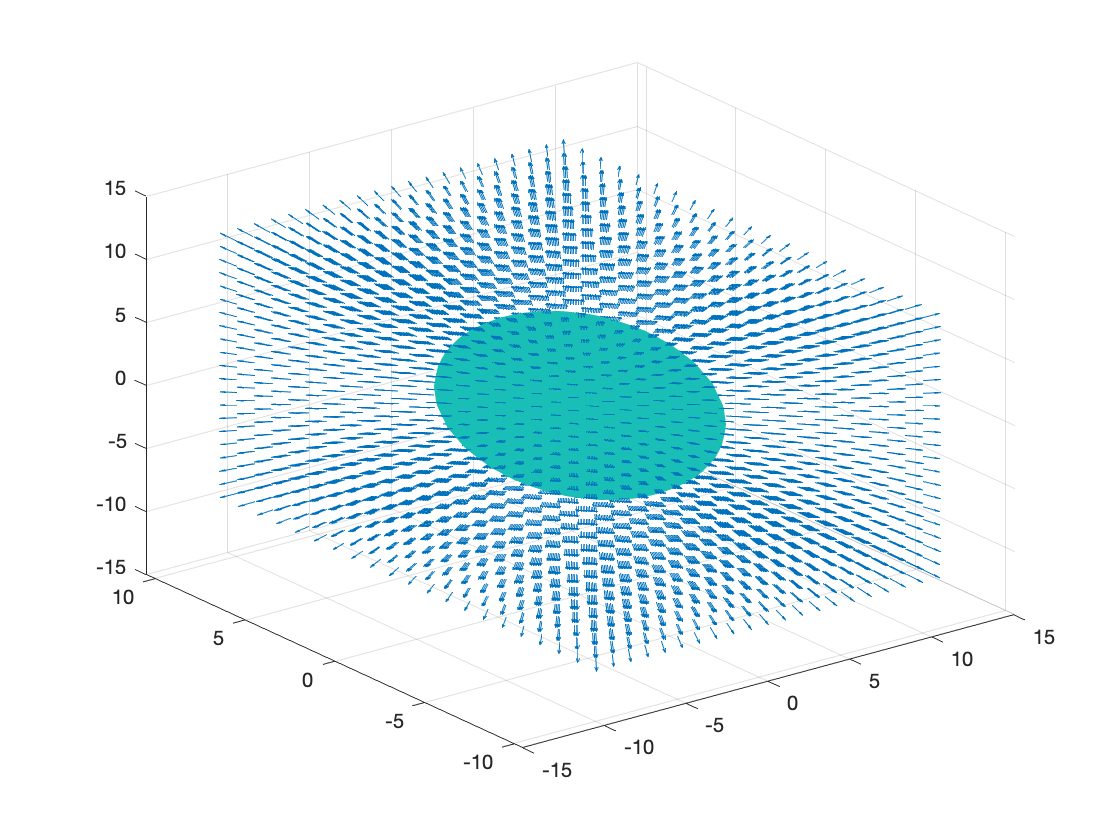

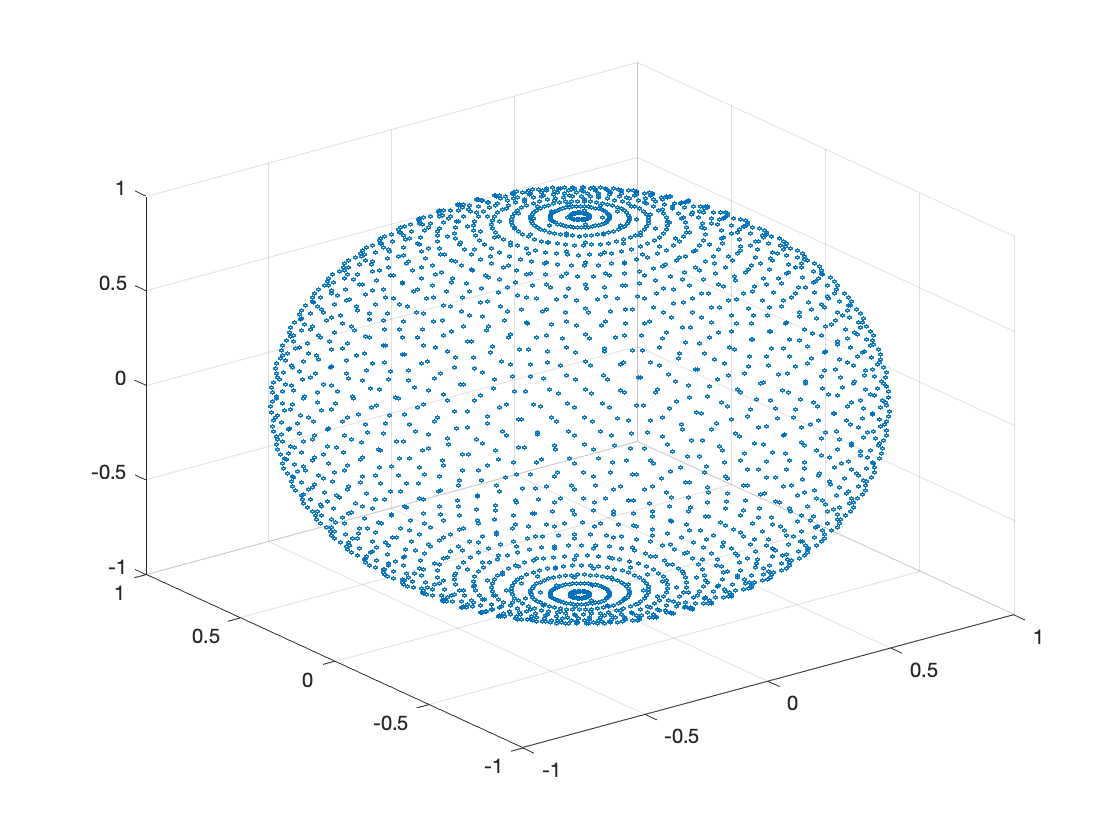

x = -10:1:10;
y = -10:1:10;
z = -10:1:10;

dx = -5:0.5:5;
dy = dx;
dz = dy;

[X, Y, Z] = meshgrid(x,y,z);
[U, V, W] = meshgrid(dx,dy,dz);

R = sqrt(U.^2 + V.^2 + W.^2);
q = quiver3(X,Y,Z,U,V,W);

[faces,verts,colors] = isosurface(X,Y,Z,R,3,R);
patch('Vertices',verts,'Faces',faces,'FaceVertexCData',colors,...
    'FaceColor','interp','EdgeColor','interp')

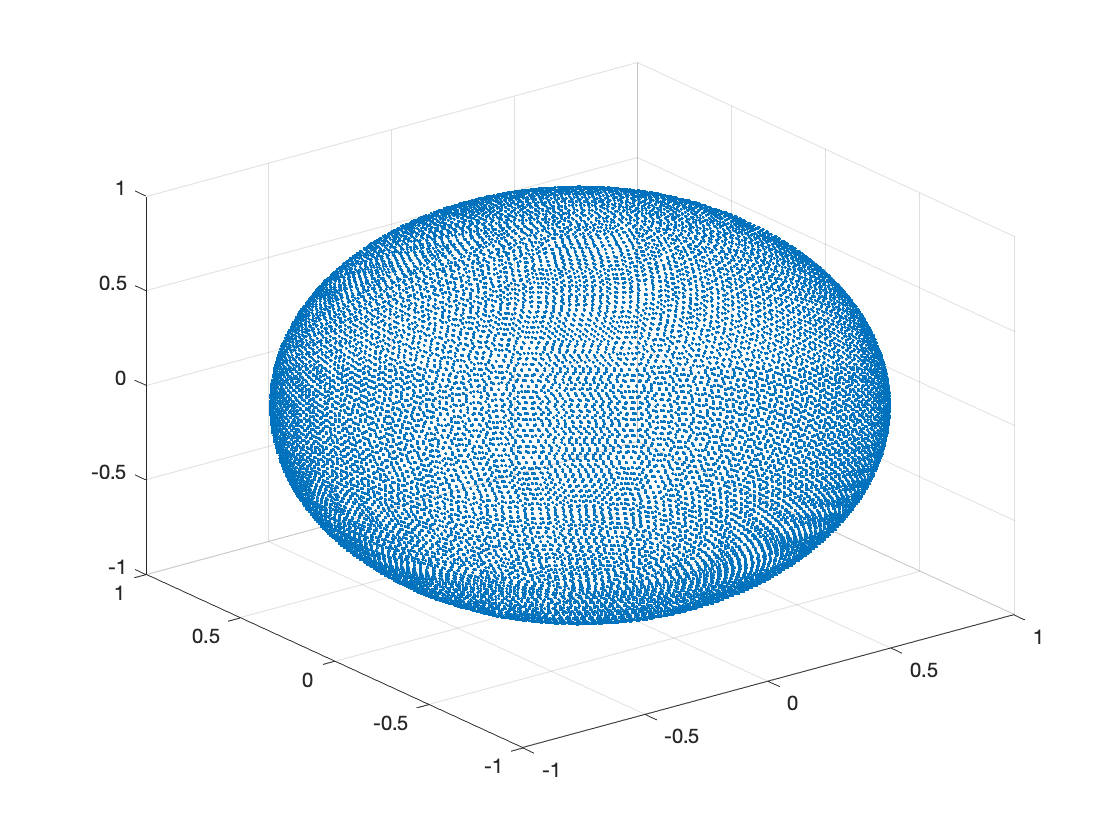

[X,Y,Z,n] = mySphere(20000);
scatter3(X,Y,Z,0.3)

nQ = 10;
xC = linspace(-1,1,nQ);
yC = linspace(-1,1,nQ);
zC = linspace(-1,1,nQ);
[xC,yC,zC] = meshgrid(xC,yC,zC);
points = [xC(:),yC(:),zC(:)];
xC = points(:,1);
yC = points(:,2);
zC = points(:,3);
nQ = length(xC)

nQ = 1000